Load in data from the work space

 load("loadInData.mat");
data = loadInData;

|==========================================================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  Activations |  Standardize |       Lambda | LayerWeights-| LayerBiasesI-|            LayerSizes |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |              | Initializer  | nitializer   |                       |
|==========================================================================================================================================================================|
|    1 | Best   |      5.7317 |      1.8793 |      5.7317 |      5.7317 |         none |        false |   2.0891e-08 |       glorot |        zeros | [ 50   2   2]         |
|    2 | Best   |      5.7257 |      47.451 |      5.7257 |       5.726 |         relu |         true |       8.0332 |           he |  

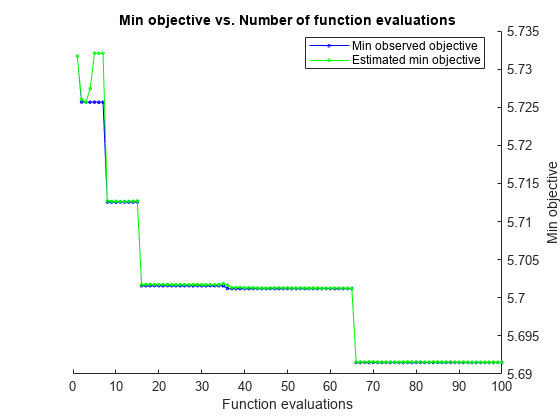


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 100 reached.
Total function evaluations: 100
Total elapsed time: 2263.9221 seconds
Total objective function evaluation time: 2200.0132

Best observed feasible point:
    Activations    Standardize      Lambda      LayerWeightsInitializer    LayerBiasesInitializer    LayerSizes
    ___________    ___________    __________    _______________________    ______________________    __________

       relu           true        1.7569e-09            glorot                      ones              4    288 

Observed objective function value = 5.6915
Estimated objective function value = 5.6915
Function evaluation time = 112.4223

Best estimated feasible point (according to models):
    


electrical_load = data.AC;

% Prepare data for training
input_window_size = 168; % 7 days of hourly data
output_window_size = 24; % 1 day ahead prediction
total_window_size = input_window_size + output_window_size;

% Prepare the input and target series
n = length(electrical_load)/input_window_size;
X = [data.AC(1:end-1)];

T = data.AC(2:end);
% 
% for i = 1:(n -  1)
%     idx=1+(i-1)*input_window_size;
%     X(:,i) =  electrical_load(idx:idx + input_window_size - 1)';
%     T(:,i) =  electrical_load(idx + input_window_size:idx + total_window_size - 1)';
% end


% Split data into training and testing sets
train_ratio = 0.7;
num_train = floor(length(X) * train_ratio);
X_train = X(1:num_train);
T_train = T(1:num_train);
X_test = X(num_train+1:end);
T_test = T(num_train+1:end);

% Create and Train Neural Network

opt = struct("ShowPlots",true,"MaxObjectiveEvaluations",100);
net = fitrnet(X_train, T_train,"OptimizeHyperparameters","all","HyperparameterOptimizationOptions", opt);


% Perform Forecast

timeStep= 1;
for j = 1:(floor(length(X_test)/timeStep)-ceil(24/timeStep)-71)
   
    offset = j*timeStep+71 ;
    
    input = X_test(1:offset); 
    first_forecast = predict(net, input);
    Yin = first_forecast(end:end);
    Y = zeros(24,1);
    Y(1) = Yin;
      
    for i=2:24
        input = [input(2:end)' Y(i-1)'];
        input = input';
        YNext = predict(net, input);
        Y(i)  = [YNext(end:end)];

    end
    
    Ypred{j}(:) = Y(:);
    Yactual{j}(:) = T_test(offset:offset+23);
end

YmapeHr = zeros(24,1);
Yrmse   = zeros(24,1);
YseCal = zeros(24,1);

for i=1:j
Ymape{i}(:) = abs(Yactual{i} - Ypred{i})./(Yactual{i})*100;
YmapeHr(:) = YmapeHr + Ymape{i}(:);

YseCal(:) = YseCal(:) + (Yactual{i}(:) - Ypred{i}(:)).^2;
end

YmapeHr = YmapeHr./j;
Yrmse = sqrt(YseCal./j);


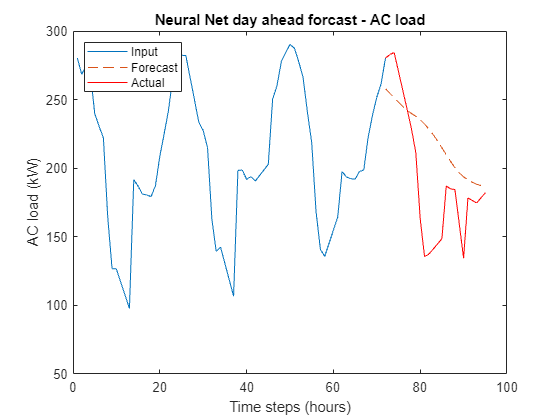


plot(1:72 , T_test(1:72))

hold on
plot(72:95, Ypred{1},"--")
plot(72:95, Yactual{1},"r")

ylabel("AC load (kW)")
xlabel("Time steps (hours)")
title("Neural Net day ahead forcast - AC load")
legend("Input", "Forecast", "Actual", "Location","northwest")

hold off

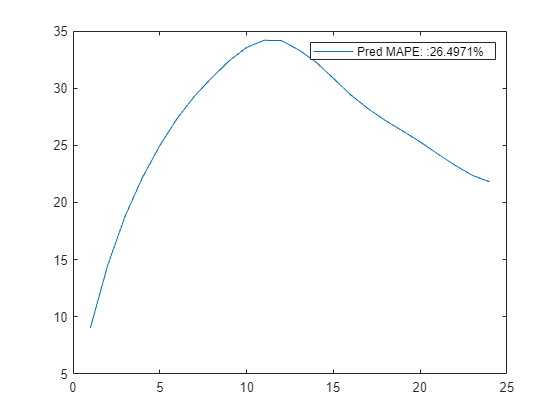




plot(YmapeHr)
legend("Pred MAPE: :" + mean(YmapeHr) +"%")

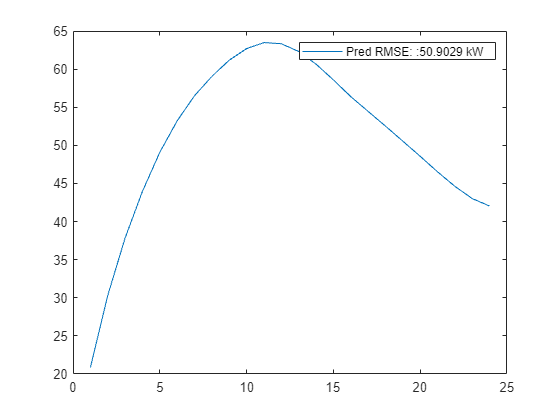


plot(Yrmse)
legend("Pred RMSE: :" + mean(Yrmse) +" kW")